XAS = (1/3).*(ax(1.272e4:1.352e4)+axJ(1.8129e4:1.8929e4)+axE(7799:8599))

XAS =     3.0319
    3.4623
    3.7464
    3.4738
    2.8795
    1.9265
    0.2703
   -1.8934
   -3.7681
   -4.2812


YAS = (1/3).*(ay(1.272e4:1.352e4)+ayJ(1.8129e4:1.8929e4)+ayE(7799:8599))

YAS =     1.1448
    3.6484
    6.7269
   11.0339
   16.0900
   19.4303
   19.4003
   19.0751
   15.5345
   10.2493


ZAS = (1/3).*(az(1.272e4:1.352e4)+azJ(1.8129e4:1.8929e4)+azE(7799:8599))

ZAS =    -1.3128
   -2.1514
   -3.4664
   -5.2528
   -6.4716
   -7.0252
   -5.7909
   -3.1753
   -0.6604
    1.7797


figure
xoutput = [];
youtput = [];
zoutput = [];
for n = 1:length(XAS)
    try
        xp1 = XAS(n+1);
    catch
        xp1 = 0;
    end
    try
        xp2 = XAS(n+2);
    catch
        xp2 = 0;
    end
    
    try
        xm1 = XAS(n-1);
    catch
        xm1 = 0;
    end
    try
        xm2 = XAS(n-2);
    catch
        xm2 = 0;
    end
    xoutput = [xoutput,(1/5)*(xp2 + xp1 + XAS(n) + xm1 + xm2)];
    
    try
        yp1 = YAS(n+1);
    catch
        yp1 = 0;
    end
    try
        yp2 = YAS(n+2);
    catch
        yp2 = 0;
    end
    
    try
        ym1 = YAS(n-1);
    catch
        ym1 = 0;
    end
    try
        ym2 = YAS(n-2);
    catch
        ym2 = 0;
    end
    youtput = [youtput,(1/5)*(yp2 + yp1 + YAS(n) + ym1 + ym2)];
    
    try
        zp1 = ZAS(n+1);
    catch
        zp1 = 0;
    end
    try
        zp2 = ZAS(n+2);
    catch
        zp2 = 0;
    end
    
    try
        zm1 = ZAS(n-1);
    catch
        zm1 = 0;
    end
    try
        zm2 = ZAS(n-2);
    catch
        zm2 = 0;
    end
    zoutput = [zoutput,(1/5)*(zp2 + zp1 + ZAS(n) + zm1 + zm2)];
end

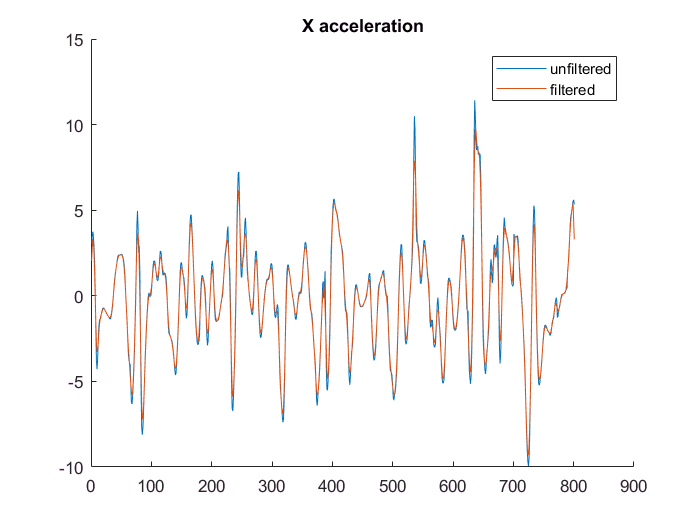

figure
hold on
plot(XAS)
plot(xoutput)
title('X acceleration')
legend('unfiltered','filtered')
hold off

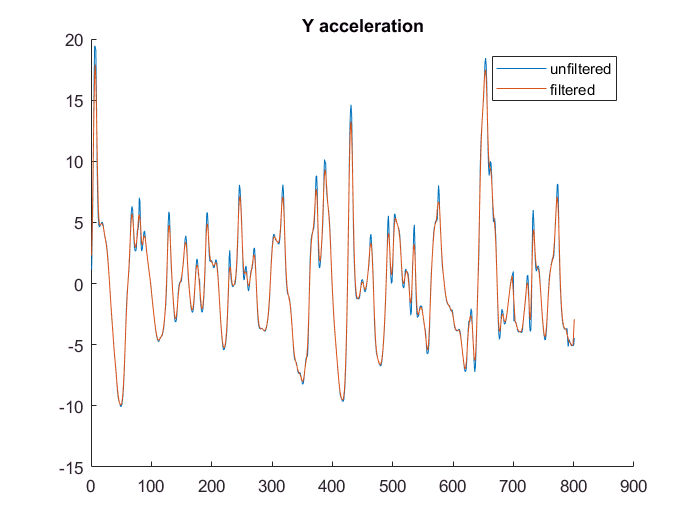


figure
hold on
plot(YAS)
plot(youtput)
title('Y acceleration')
legend('unfiltered','filtered')
hold off

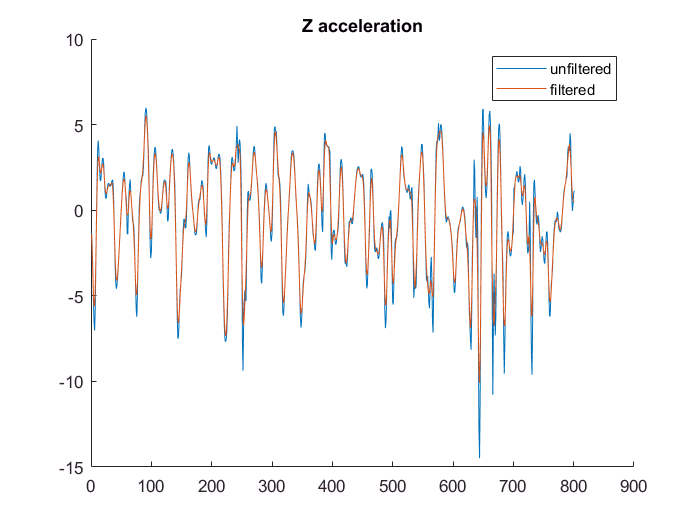


figure
hold on
plot(ZAS)
plot(zoutput)
title('Z acceleration')
legend('unfiltered','filtered')
hold off

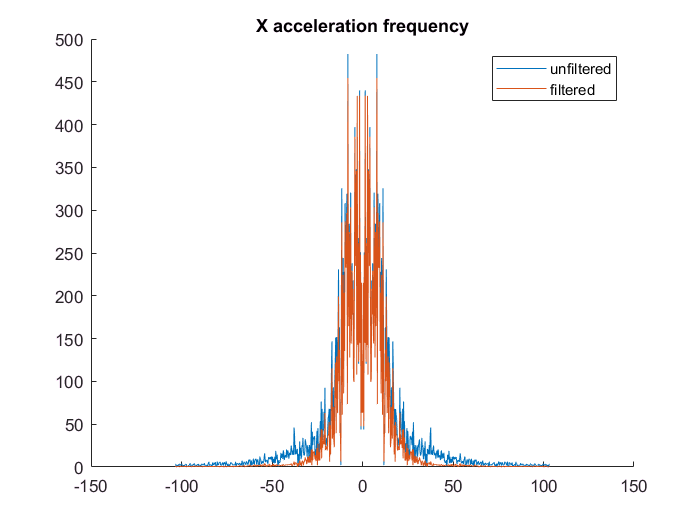

NS = length(XAS);
Fs = 207;
freqspaceS = linspace(-Fs/2, Fs*(1-1/NS)/2, NS);

figure
hold on
plot(freqspaceS, fftshift(abs(fft(XAS))))
plot(freqspaceS, fftshift(abs(fft(xoutput))))
title('X acceleration frequency')
legend('unfiltered','filtered')
hold off

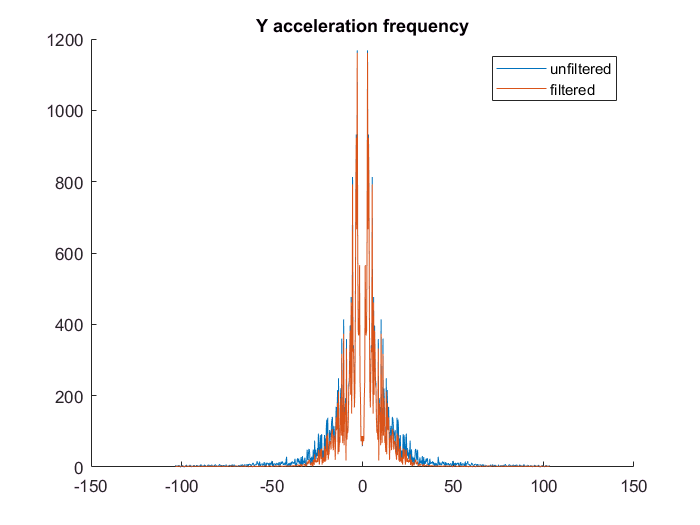


figure
hold on
plot(freqspaceS, fftshift(abs(fft(YAS))))
plot(freqspaceS, fftshift(abs(fft(youtput))))
title('Y acceleration frequency')
legend('unfiltered','filtered')
hold off

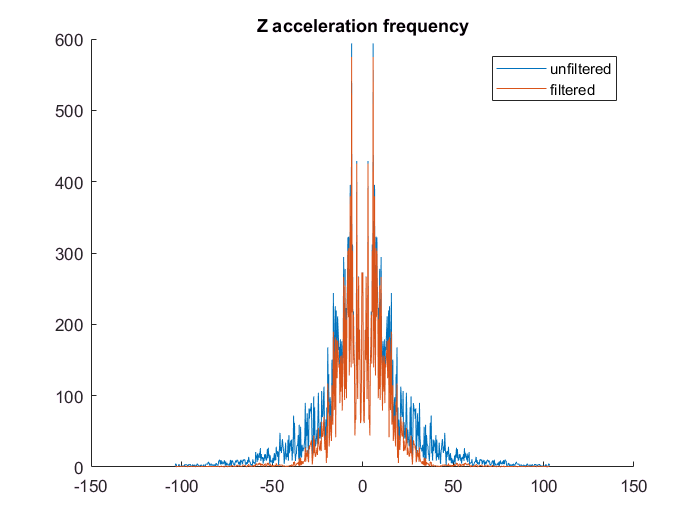


figure
hold on
plot(freqspaceS, fftshift(abs(fft(ZAS))))
plot(freqspaceS, fftshift(abs(fft(zoutput))))
title('Z acceleration frequency')
legend('unfiltered','filtered')
hold off